В данном Live скрипте будет реализовано разделение выборки на подвыборки для тренировки, валидации и тестирования моделей. Далее будет созданы датасеты с полиномиальными признаками. Затем будут рассмотрены, обучены и протестированы 2 классификатора: Байесовский и логистическая регрессия. В данной работе также присутствует классификатор "K ближайших соседей" в оригинальных терминах - K Nearest Neighbors (KNN), которому не требуется обучение. Классификатор KNN будет задействован на этапе рассмотрения и тестирования.

**Разделение выборки на подвыборки**

%загружаем предварительно извлеченные признаки
X = readmatrix('TableDatasets/X_GenShapes_NO_rot_NO_shift_N33.txt');
y = readmatrix('TableDatasets/y_GenShapes_NO_rot_NO_shift.txt');
[row, col] = find(isnan(X)); %Поиск nan значений

%{
n_obj_in_class - задействуемое количество объектов от каждого класса из
исходного датасета. Данное число должно быть не больше, чем количество
меющихся объектов данного класса. В ином случае появляется сообщение об
ошибке. 
%}
n_obj_in_class = 4500;
% пропорции получаемых подвыборок
proportions = [60,20,20];
[X_train,X_cv,X_test,y_train,y_cv,y_test] = split_dataset(X,y,n_obj_in_class,proportions);

**Генерация полиномиальных признаков**

Генерация полиномиальных признаков заключается в получении дополнительных признаков из исходных путем перемножения между собой. Такая операция позволяет получить датасет, на котором можно решать нелинейные задачи линейным классификатором. Разделяющая поверхность в признаковом пространстве может иметь иметь некоторый полиномиальный порядок кривизны, следовательно, сформировав нелинейные признаки, можно на них решать задачу линейным классификатором. **В данной работе используется генерация признаков 2 порядка. **Данное решение связано со скоростью роста количества признаков от степени полинома.

*Пример формирования признаков 2 степени для пространства множества X1,X2,X3: *

**X1,X2,X3- > X1,X2,X3 | X1^2, X1*X2, X1*X3, X2^2, X2*X3, X3^2**

X_train_poly = generate_X_quad_features(X_train);
X_cv_poly = generate_X_quad_features(X_cv);
X_test_poly = generate_X_quad_features(X_test);

**Байесовский классификатор**

В оригинальной литературе реализуемый классификатор называют наивным Байесовским классификатором (Naive Bayes). Особенность данного классификатора в том, что близость объекта к определенному классу рассчитывается отдельно по каждому признаку (независимо), а вероятность принадлежности объекта к i-му классу определяется как произведение вероятностей принадлежности по каждому признаку. Классификация осуществляется по argmax вероятностей для каждого класса. 

 Реализованы две функции: обучение (Bayes_fit) и предсказание (Bayes_predict). Функция Bayes_fit имитирует обучение классификатора. Входные параметры функции: X_train, y_train. А именно, на вход функция обучения принимает тренировочную выборку объектов и их метки классов. Функция предсказания принимает на вход матрицу объектов X_test или X_cv, а возаращает предсказания класса для каждого объекта из входной матрицы.

Обучение и тестирование Байесовского классификатора **без использования полиномиальных признаков**

Bayes_fit(X_train,y_train);%обучение 

y_pred_np = Bayes_predict(X_test);%тестирование
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred_np)%отображение матрицы ошибок и коэффициента точности

confM =    898     0     0     0     2
     0   900     0     0     0
     0     0   900     0     0
     0     0     0   900     0
    10     0     0     0   890


accuracy = 0.9973

Обучение и тестирование Байесовского классификатора **с использованием полиномиальных признаков**

Bayes_fit(X_train_poly,y_train);%обучение 

Unrecognized function or variable 'X_train_poly'.

y_pred_np = Bayes_predict(X_test_poly);%тестирование
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred_np)%отображение матрицы ошибок и коэффициента точности

confM =    898     2     0     0     0
     0   900     0     0     0
     0     0   900     0     0
     0     0     0   900     0
   900     0     0     0     0


accuracy = 0.7996

**Логистическая регрессия**

Логистическая регрессия - классическая линейная модель машинного обучения. В оригинальном виде модель разделяет гиперплоскостью объекты в признаковом пространстве. Параметры модели характеризуют положение этой гиперплоскости. Для формирования прогноза вероятности того, что объект относится к нулевому или первому классу используется приведение предсказанной моедлью непрерывной велечины сигмоидной функцией. Предсказаная моделью непрерывная величина - скалярное произведение вектора параметров модели и вектора признаков объекта. Для обобщения бинарной классификации на многоклассовую используется подход "один против всех". В данном подходе классификатор на N классов является комбинацией из N бинарных классификаторов. Каждый отдельный классиифкатор отделяет i-ый класс от всех остальных гиперплоскостью в признаковом пространстве. Реализованы функции обучения и предсказания (fit_log_reg и predict_log_reg).

Обучение и тестирование логистической регрессии **без использования полиномиальных признаков**

lambda = 0; % настраиваемый параметр - коэффициент регуляризации
alpha = 0.03; % настраиваемый параметр - скорость обучения
%{
В результате обучения сохраняется матрица параметров бинарных
классификаторов. Столбцы - вектора параметров классификатора i-го класса.
Функция обучения возвращает кривые обучения для валидационной и
тренировочной выборок. Кривая обучения - значения функции ошибки (функции стоимости) на каждой итерации обучения. Данная кривая является средней по всем бинарным
классификаторам. Она имеет скачки из-за того, что обучения одного
класисифкатора заканчивалось раньше, чем второго.
%}

[j_train, j_cv] = fit_log_reg(X_train,y_train,X_cv,y_cv,lambda,alpha);

Количество итераций на классе №1 =1754
Количество итераций на классе №2 =7657
Количество итераций на классе №3 =9053
Количество итераций на классе №4 =8952
Количество итераций на классе №5 =1300


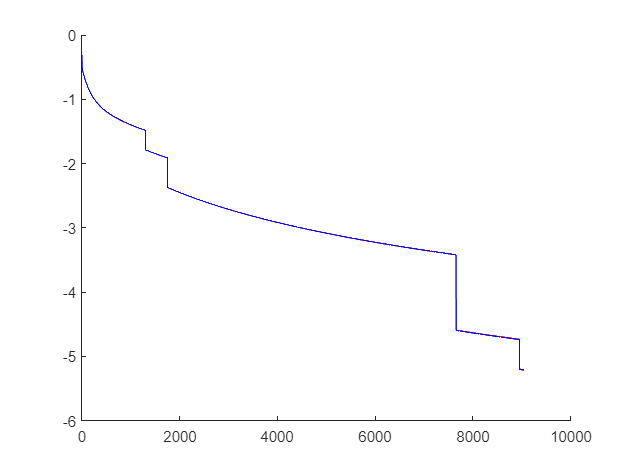

figure;
hold on 
plot(log(j_train),'color','r','DisplayName','log(J_train)');
plot(log(j_cv),'color','b','DisplayName','log(J_cv)');
hold off

y_pred = predict_log_reg(X_test);
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred)

confM =    811     0     0     0    89
     2   897     0     0     1
     0     0   900     0     0
     0     0     0   900     0
    49     0     0     0   851


accuracy = 0.9687

Обучение и тестирование логистической регрессии **с использованием полиномиальных признаков**

lambda = 0; % настраиваемый параметр - коэффициент регуляризации
alpha = 0.03; % настраиваемый параметр - скорость обучения
[j_train, j_cv] = fit_log_reg(X_train_poly,y_train,X_cv_poly,y_cv,lambda,alpha);

Количество итераций на классе №1 =4488
Количество итераций на классе №2 =5716
Количество итераций на классе №3 =7845
Количество итераций на классе №4 =8506
Количество итераций на классе №5 =5475


y_pred_poly = predict_log_reg(X_test_poly);
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred_poly)

confM =    888     2     0     0    10
     0   899     0     0     1
     0     0   900     0     0
     0     0     0   900     0
     5     0     0     0   895


accuracy = 0.9960

** Классификатор KNN - К ближайших соседей**

Классификатор не нуждается в обучении, в процессе его работы для предсказания класса входного объекта (вектора признаков) в пространстве обучающей выборки выполняется поиск K ближайших объекторв. Расстояния рассчитывается по Евклидовой метрике в многомерном признаковом пространстве. Средни найденных K ближайших соседей выбирается наиболее часто встречающийся класс, этот класс и присваивается входному объекту. Очевидный недостаток алгоритма - высокая вычислительная сложность. Если размерность признакового пространства K, объектов в обучающай выборке m_об, а в тестовой m_тест, то оценка количества операций может быть сделана как O(K*m_об*m_тест).

K = 3; % количество искомых ближайших соседей 
y_pred = KNN_classification(X_train,y_train,K,X_test);
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred)

confM =    900     0     0     0     0
     0   900     0     0     0
     0     0   900     0     0
     0     0     0   900     0
     0     0     0     0   900


accuracy = 1

save X_train X_train
save y_train y_train

**Классификатор: решающие деревья**

TreeMLmodel = fitctree(X_train,y_train)

TreeMLmodel =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3 4 5]
           ScoreTransform: 'none'
          NumObservations: 13500


  Properties, Methods


y_pred = predict(TreeMLmodel,X_test);
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred)

confM =    900     0     0     0     0
     0   900     0     0     0
     0     0   900     0     0
     0     0     0   900     0
     3     0     0     0   897


accuracy = 0.9993

save TreeMLmodel.mat TreeMLmodel

**SVM Классификатор**

SVMmodel = fitcecoc(X_train,y_train)

SVMmodel =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2 3 4 5]
           ScoreTransform: 'none'
           BinaryLearners: {10×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


y_pred = predict(SVMmodel,X_test);
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred)

confM =    898     0     0     0     2
     0   900     0     0     0
     0     0   900     0     0
     0     0     0   900     0
     8     0     0     0   892


accuracy = 0.9978

save SVMmodel SVMmodel

**Random forest**

RandForestModel = fitrensemble(X_train,y_train);

y_pred = predict(RandForestModel,X_test);
y_pred = round(y_pred);
[confM,accuracy] = calc_confusion_matrix(y_test,y_pred)

confM =    878    10     1     1     0
     0   900     0     0     0
     0     3   897     0     0
     0     0     0   900     0
     0     0     3     7   885


accuracy = 0.9911

save RandForestModel RandForestModel